# Constants

clear;

## Right Image

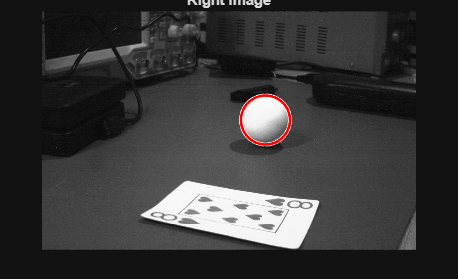

rightImage = imread("images\right5.jpg");
rightGray  = rgb2gray(rightImage);

figure(1);
imshow(rightGray); hold on;
[centersR, radiiR, metricR] = imfindcircles(rightGray, [15 100]);
viscircles(centersR, radiiR, 'EdgeColor', 'red');   
title("Right image");

[~, iR] = max(metricR); % use the "best" circle
uR = centersR(iR, 1)

uR = 449.8044

vR = centersR(iR, 2)

vR = 219.4127

## Left Image

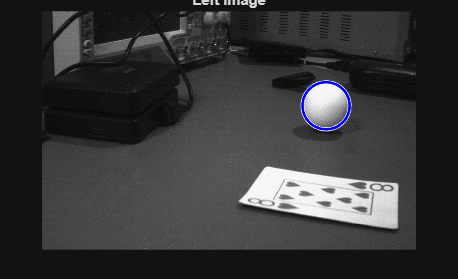


leftImage = imread("images\left5.jpg");
leftGray  = rgb2gray(leftImage);

figure(2);
imshow(leftGray); hold on;
[centersL, radiiL, metricL] = imfindcircles(leftGray, [15 100]);
viscircles(centersL, radiiL, 'EdgeColor', 'blue');
title("Left image");

[~, iL] = max(metricL); % use the "best" circle
uL = centersL(iL, 1)

uL = 571.6662

vL = centersL(iL, 2)

vL = 190.7408

## Constants

% default values from LAB document
b = 50; % baseline [mm]
px = 0.006; % pixel size [mm]
f = 6; % focal length [mm]
fpx = f / px; % focal length [px]
xNumPix = size(leftGray, 2) % num pix x [px]

xNumPix = 752

yNumPix = size(leftGray, 1) % num pix y [px]

yNumPix = 480

cxOrigin = xNumPix/2; % Origin camera x center [px]
cyOrigin = yNumPix/2; % Origin camera y center [px]
cxBaseline = xNumPix/2; % Camera baseline distance x center [px]
cyBaseline = yNumPix/2 ; % Camera baseline distance y center [px]

## 3D Centroid

d = uL - uR % disparity [px]

d = 121.8618


z = (fpx * b) / d % depth [mm]

z = 410.3008

x = (uL - cxOrigin) * z / fpx % x cord [mm]

x = 80.2820

y = -(vL - cyOrigin) * z / fpx % y cord [mm]

y = 20.2111